# MAS416 - Test preparation, Mechanical level 2, Tutorial 3

## Problem 1

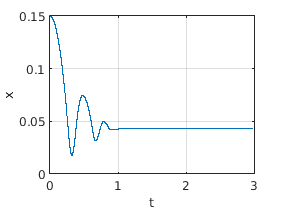

clc; clear all; close all;

muk = 0.2;
vtnh = 0.02; % m/s

m = 200; % kg
g = 9.81; % m/s^2
theta = deg2rad(30); % rad
L0 = 50/10^3; % m
k = 150*10^3; % N/m
b = 4000; % Ns/(m*m^0.5)

x = 150/10^3; % m
xDot = 0; % m/s

t = 0; % s
simTime = 3; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculations

    delta = L0-x; % delta becomes positive when x is smaller than L0
    deltaDot = -x;

    % Fb force as given in task
    if(delta >= 0)
        Fb = b*sqrt(delta)*deltaDot;
    else
        Fb = 0;
    end

    % Restricting Fk to what makes sense
    if(delta >= 0)
        Fk = k*delta;
    else
        Fk = 0;
    end

    % Gravitational force
    Fg = m*g*sin(theta);

    % Friction force modelled as tangent hyperbolic function muh
    % CAREFUL!
    % Equation 2.10 in notes says tanh(x2Dot - x1Dot), therefore -xDot!
    muh = muk * tanh(-xDot/vtnh);
    Ffr = m*g*muh;

    % Fb and Fk will push on mass in positive x direction when mass is in
    % contact with spring and damper. Gravitational force is acting in the
    % negative x direction, and the friction force is acting opposite of
    % where the mass is going.
    sumF = Fb+Fk-Fg+Ffr;
    
    % F = ma -> a = F/m
    xDotDot = sumF/m;

    % Logging
    t_plt(idx) = t;
    x_plt(idx) = x;
    xDot_plt(idx) = xDot;

    % Time integration
    xDot = xDot + xDotDot * dt;
    x = x + xDot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, x_plt)
xlabel("t")
ylabel("x")
grid

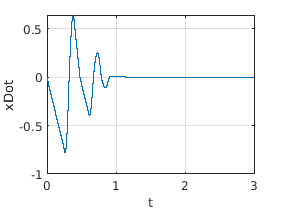

plot(t_plt, xDot_plt)
grid
xlabel("t")
ylabel("xDot")

## Problem 2

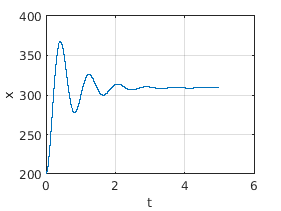

clc; clear all;

m1 = 100; % kg
m2 = 200; % kg
g = 9.81; % m/s^2
L0 = 200/10^3; % m
k = 18*10^3; % N/m
b = 900; % Ns/m

x = 200/10^3; % m
xDot = 0; % m/s

t = 0; % s
simTime = 5; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculations

    delta = x-L0;
    deltaDot = xDot;

    Fk = k*delta;
    Fb = b*deltaDot;

    Fm2 = m2*g;

    sumF = -Fk-Fb+Fm2;

    xDotDot = sumF/(m1+m2);

    % Logging
    t_plt(idx) = t;
    x_plt(idx) = x*10^3;
    xDot_plt(idx) = xDot*10^3;

    % Time integration
    xDot = xDot + xDotDot * dt;
    x = x + xDot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, x_plt)
xlabel("t")
ylabel("x")
grid

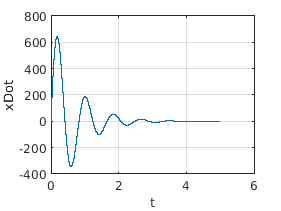

plot(t_plt, xDot_plt)
grid
xlabel("t")
ylabel("xDot")

## Problem 3

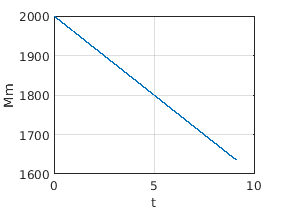

clc; clear all;

Jm = 0.8; % km*m^2
J1 = 0.1; % km*m^2
J2 = 1.5; % km*m^2
Jd = 8;   % km*m^2

m = 10000; % kg
g = 9.81; % m/s^2

r1 = 80/10^3; % m
r2 = 480/10^3; % m
rd = 600/10^3; % m
L0 = 10; % m
i = r2/r1;

Mm_max = 2*10^3; % Nm
Mm_min = -Mm_max; % Nm

thetaDot_m_middle = 50; % rad/s

t = 0;
simTime = 3;
dt = 10^-5;
idx = 1;

thetaDot = 0;

while(t <= simTime)
    % Calculations

    % Ramp
    Mm = Mm_max - Mm_max / thetaDot_m_middle * thetaDot;

    Jeff = Jm + J1 + (J2+J1)/i^2 + (J2+Jd+m*rd^2)/i^4;
    Meff = (m*g*rd)/i^2;

    thetaDotDot = (Mm - Meff)/Jeff;

    % Logging
    t_plt(idx) = t;
    thetaDot_plt(idx) = thetaDot;
    Mm_plt(idx) = Mm;

    % Time integration
    thetaDot = thetaDot + thetaDotDot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(thetaDot_plt, Mm_plt)
grid
xlabel("t")
ylabel("Mm")

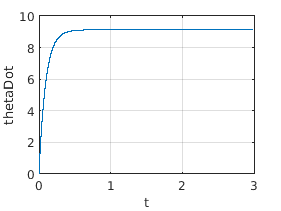


plot(t_plt, thetaDot_plt)
grid
xlabel("t")
ylabel("thetaDot")

## Problem 4

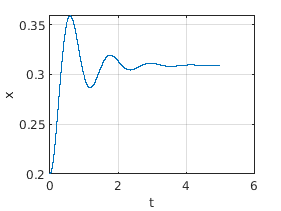

clc; clear all;

m1 = 400; % kg
m2 = 200; % kg
g = 9.81; % m/s
L0 = 200/10^3; % m
k = 36*10^3; % N/m
b = 3200; % Ns/m

x = 200/10^3; % m
xDot = 0; % m/s

t = 0;
simTime = 5;
dt = 10^-5;
idx = 1;

while(t <= simTime)
    % Calculations

    delta = x-L0;
    deltaDot = xDot;

    Fk = k*delta;
    Fb = b*deltaDot;
    Fm2 = m2*g;

    sumF = -Fk-Fb+2*Fm2;

    %Ekin = 1/2*m1*xDot^2 + 1/2*m2*(2*xDot)^2 ==>> m1 + 4*m2
    xDotDot = sumF/(m1+4*m2);

    % Logging
    t_plt(idx) = t;
    xDot_plt(idx) = xDot;
    x_plt(idx) = x;

    % Time integration
    xDot = xDot + xDotDot * dt;
    x = x + xDot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, x_plt)
grid
xlabel("t")
ylabel("x")

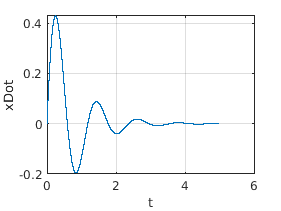

plot(t_plt, xDot_plt)
grid
xlabel("t")
ylabel("xDot")

## Problem 5

clc; clear all;

k = 10^7; % N/m
b = 2*10^4; % Ns/m

Jm = 0.8; % km*m^2
J1 = 0.1; % km*m^2
J2 = 1.5; % km*m^2
Jd = 8;   % km*m^2

m = 10000; % kg
g = 9.81; % m/s^2

r1 = 80/10^3; % m
r2 = 480/10^3; % m
rd = 600/10^3; % m
L0 = 10 + m*g/k; % m
i = r2/r1;

Mm_max = 2*10^3; % Nm
Mm_min = -Mm_max; % Nm

thetaDot_m_middle = 50; % rad/s

t = 0;
simTime = 3;
dt = 10^-5;
idx = 1;

thetaDot = 0;

while(t <= simTime)
    % Calculations

    % Logging

    % Time integration

    % Update variables
    t = t + dt;
    idx = idx + 1;

end